# **The heat equation**

## 1. Introduction

- Let's assume a 1-dimensional rod with length $L>0$ made of an isotropic material,

- The function $T(x,t)$ describes the heat of a point $x$ at time $t$, $x \in [ 0,L ]$, $t \in [0,\infty)$,

- At $t=0$, the rod has some initial heat distribution $T(x,0) = \phi(x)$,

- We assume no heat exchange with the enviornment.

Knowing that, is there a way to know how the heat distribution in the object changes over time? 

## 2. Joseph Fourier's study of heat flow

*The Analytical Theory of Heat *(fr. *Théorie analytique de la chaleur*) is Fourier's 1822 publication on heat flow. His work was based on Isaac Newton's law of cooling, which states:

***"The rate of heat loss of a body is directly proportional to the difference in the temperatures between the body and its environment."***

It is in this book where he famously stated, that any function can be expressed as an infinite sum of sine waves, which led to the invention of the fourier series and later, the fourier transform.

### The heat equation for 3 dimensions:

    
$$\frac{\partial T}{\partial t} = \alpha \cdot \left( \frac{\partial^2 T}{\partial x^2}+\frac{\partial^2 T}{\partial y^2}+\frac{\partial^2 T}{\partial z^2} \right)$$


which can also be generalized as:

    $\frac{\partial T}{\partial t} = \alpha \cdot \nabla^2 T$ , where $\nabla^2$ is the laplacian operator

## 4. Heat flow in a 1-dimensional rod

Let's first look at a simplified example with a 1-dimensional rod insulated at both ends (No heat lost to the enviornment) and with an initial heat distribution $\phi (x)$

### Simulation parameters

rod_length = 10;
runtime = 0.5;
length_resolution = 50;
time_resolution = 200;
position = linspace(0,rod_length,rod_length*length_resolution + 1);
time = linspace(0,runtime,runtime*time_resolution + 1);

### Boundary conditions

left_end_state = 0;
right_end_state = 0;

if you chose a constant temperature for any end, set it here

left_end_constant_temperature = 0;
right_end_constant_temperature = 0;
bc_choice = [left_end_state, left_end_constant_temperature, right_end_state, right_end_constant_temperature];
bcs = boundary_conditions(bc_choice);

### Temperature distribution selection 

ic_choice = 4;

#### Controls for two peaks

first_peak_middle = 1;
second_peak_middle = 9;
first_peak_value = 50;
second_peak_value = 50;
first_peak_thickness = 0.001;
second_peak_thickness = 0.001;

#### Controls for sin

frequency =2;
amplitude = 10;

#### Controls for constant value

constant_temperature = 0;

#### Controls for discontinuous

left_side_temperature = 1000;
right_side_temperature = 300;
discontinuity_point = 5;

### Slice selection

x_step = rod_length/(rod_length*length_resolution);
slice_x_value = 5;
slice_x_value_index = find(position == slice_x_value,1);

params = { ...
    first_peak_middle...
    second_peak_middle...
    first_peak_value...
    second_peak_value...
    first_peak_thickness...
    second_peak_thickness...
    frequency...
    amplitude...
    constant_temperature...
    left_side_temperature...
    right_side_temperature...
    discontinuity_point
    };
phi = initial_conditions(ic_choice, params);
sol = pdepe(0,@heatpde,phi,bcs,position,time);

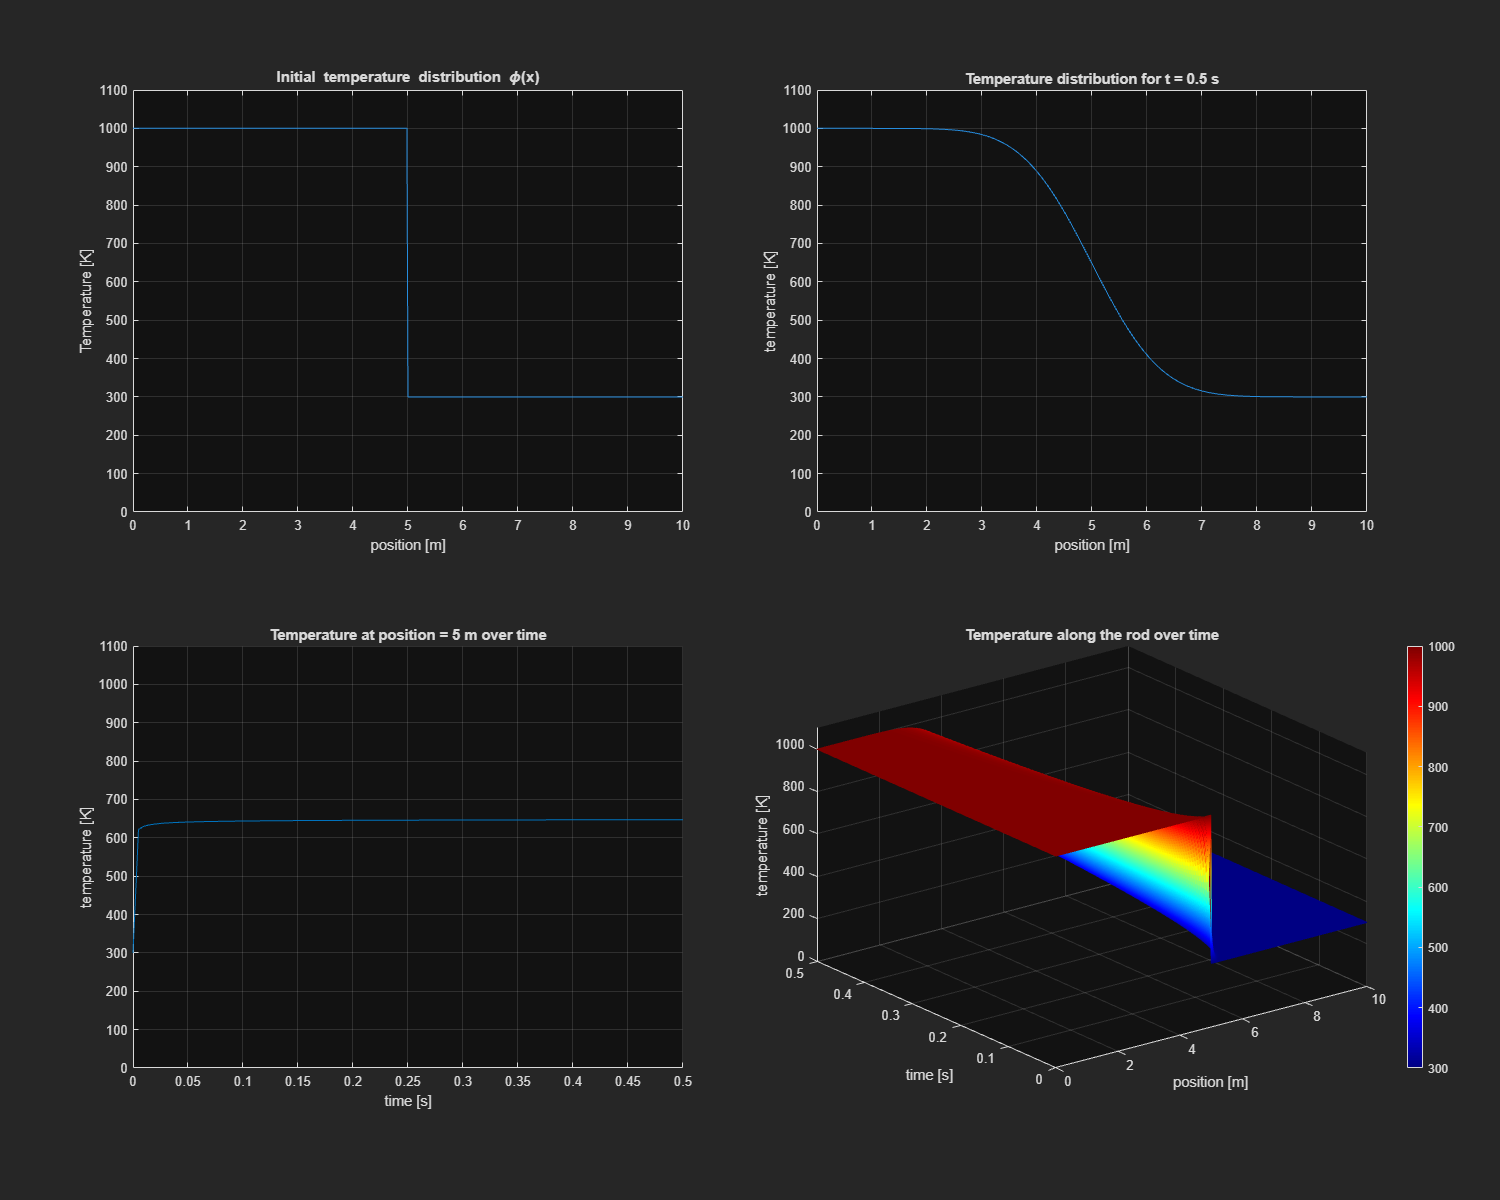

 
figure('name','Heat_flow_simulation','Position',[100 100 1500 1200])
colorPropObjs = findobj(gcf, "-property", "Color");
colorPropObjs(1).Color = [0.1490 0.1490 0.1490];
y_axis_max_value = 1.1 * max(phi(position));
tiledlayout(2,2)
nexttile
    plot(position, phi(position));
    xlim([0 rod_length])
    ylim([0 y_axis_max_value])
    grid on
    title("Initial temperature distribution \phi(x)")
    xlabel("position [m]")
    ylabel("Temperature [K]")
    colormap('jet')
nexttile
    p_1 = plot(position,sol(1,:));
    hold on
    grid on
    xlim([0 rod_length])
    ylim([0 y_axis_max_value])
    t_1 = title("Temperature distribution for t =");
    xlabel("position [m]")
    ylabel("temperature [K]")
nexttile
    p_2 = animatedline('Color',[0 0.4470 0.7410]);
    addpoints(p_2,time(1),sol(1,slice_x_value_index))
    hold on
    grid on
    xlim([0 runtime])
    ylim([0 y_axis_max_value])
    t_2 = title(strcat("Temperature at position = ", num2str(slice_x_value), " m over time"));
    xlabel("time [s]")
    ylabel("temperature [K]")
nexttile
    temp = NaN(length(time),length(position));
    temp(1,:) = sol(1,:);
    p_3 = surf(position,time,temp,'EdgeColor','interp');
    grid on
    axis ([0 rod_length 0 runtime 0 y_axis_max_value])
    title("Temperature along the rod over time")
    xlabel("position [m]")
    ylabel("time [s]")
    zlabel("temperature [K]")
    colormap("jet")
    colorbar
    

    for k = 2:length(time)
        temp(k,:) = sol(k,:);
        set(p_1,'XData',position,'YData',sol(k,:))
        set(t_1,'String',strcat("Temperature distribution for t = ", num2str(time(k))," s"))
        addpoints(p_2,time(k),sol(k,slice_x_value_index))
        set(p_3,'XData',position,'YData',time,'ZData',temp)
        drawnow
    end